# Performance for Different Choices of MC and KC

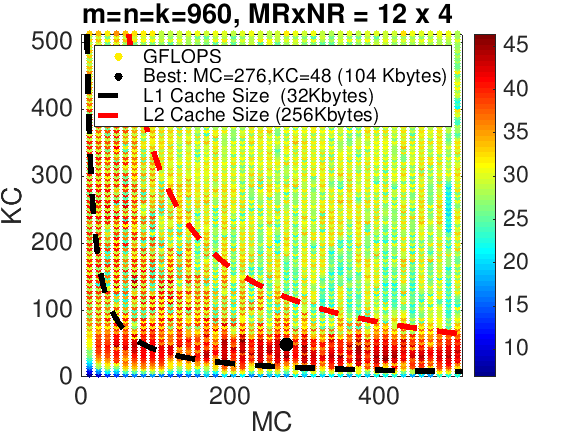

clear all

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

output_PI_JI_12x4_MCxKC        % load performance data
% output_Five_Loops_Packed_12x4Kernel_MCxKC

colorbar;   % show the color bar
colormap jet;

% create scatter plot of performance
scatter( data(:,2), data(:,3), 20, data(:,7), 'filled', ...
    'DisplayName', 'GFLOPS');

% find where the best performance is attained
[ maxvalue, imax ] = max( data(:,7) );

% put the best performing problem size on the plot
scatter( data(imax,2), data(imax,3), 100, data(imax,7), 'black', ...
    'filled', 'DisplayName', sprintf( 'Best: MC=%d,KC=%d (%d Kbytes)', ...
    data(imax,2), data( imax,3), ...
    round(data(imax,2)*data(imax,3)*8/1024) ) );

% plot the contour of the L1 cache size
Doubles_in_L1_Cache = 32*1024/8;

MC = [1:1:512];
KC = ones( size( MC ) ) * Doubles_in_L1_Cache ./ MC;
plot( MC, KC, 'LineStyle', '--', 'LineWidth', 4, ...
    'Color', 'black', ...
    'DisplayName', 'L1 Cache Size  (32Kbytes)' );

% plot the contour of the L2 cache size
Doubles_in_L2_Cache = 256*1024/8;

KC = ones( size( MC ) ) * Doubles_in_L2_Cache ./ MC;

plot( MC, KC, 'LineStyle', '--', 'LineWidth', 4, ...
    'Color', 'red', ...
    'DisplayName', 'L2 Cache Size (256Kbytes)' );


% Create ylabel
ylabel( 'KC', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'MC', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeast','FontSize',14);

axis( [0 512 0 512 ] );

% Uncomment if you want to create a png for the graph
print( 'Plot_MC_KC_Performance.png', '-dpng' );


% report the best performance attained
disp( 'best performance attained by MyGemm: (in GFLOPS)'  );

best performance attained by MyGemm: (in GFLOPS)


disp( max( data( :, 7 ) ) );

   46.4330



disp( 'best performance attained by reference: (in GFLOPS)'  );

best performance attained by reference: (in GFLOPS)



disp( max( data( :, 5 ) ) );

   59.5340

